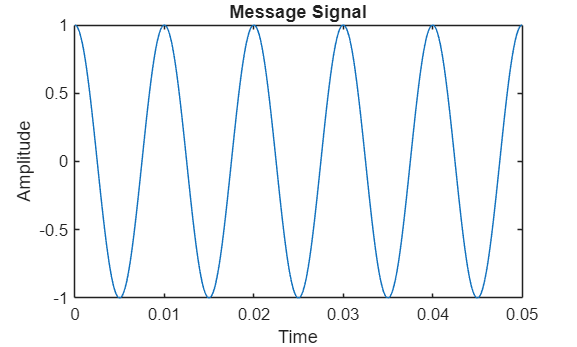

fs = 10000;
t = 0:1/fs:0.05;
fc = 1000;
fm = 100;
mu = 0.5;
SNR = 30;


m = cos(2*pi*fm*t);
c = cos(2*pi*fc*t);
dsb_am = (1 + mu * m) .* c;
dsb_sc = m .* c;
m_analytic = hilbert(m);
ssb_sc = real(m_analytic .* exp(1j*2*pi*fc*t));


dsb_am_n = awgn(dsb_am, SNR, 'measured');
dsb_sc_n = awgn(dsb_sc, SNR, 'measured');
ssb_sc_n = awgn(ssb_sc, SNR, 'measured');


m_dsb_am = abs(hilbert(dsb_am_n)) - 1;
m_dsb_sc = 2 * dsb_sc_n .* c;
m_dsb_sc = lowpass(m_dsb_sc, 1.5*fm, fs);
m_ssb_sc = 2 * ssb_sc_n .* c;
m_ssb_sc = lowpass(m_ssb_sc, 1.5*fm, fs);


figure; plot(t, m);
title('Message Signal');
xlabel('Time');
ylabel('Amplitude');

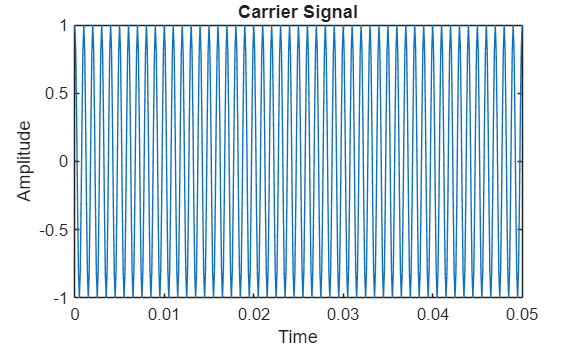


figure; plot(t, c);
title('Carrier Signal');
xlabel('Time');
ylabel('Amplitude');

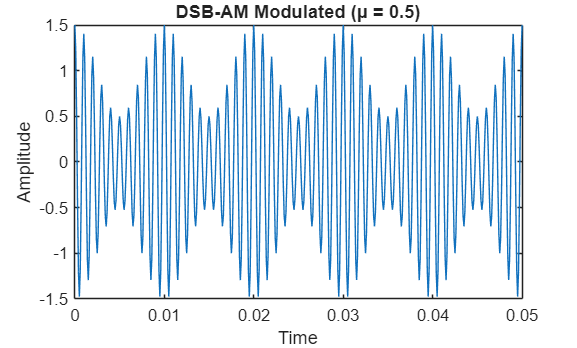


figure; plot(t, dsb_am);
title(['DSB-AM Modulated (μ = ' num2str(mu) ')']);
xlabel('Time');
ylabel('Amplitude');

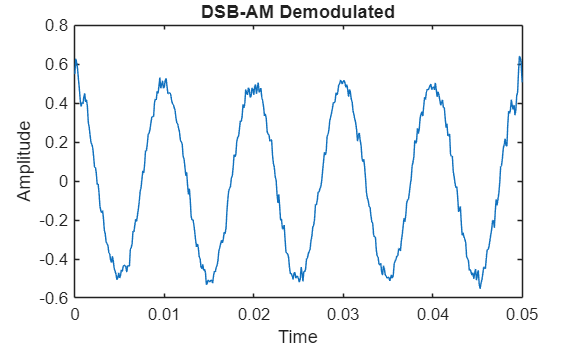


figure; plot(t, m_dsb_am);
title('DSB-AM Demodulated');
xlabel('Time');
ylabel('Amplitude');

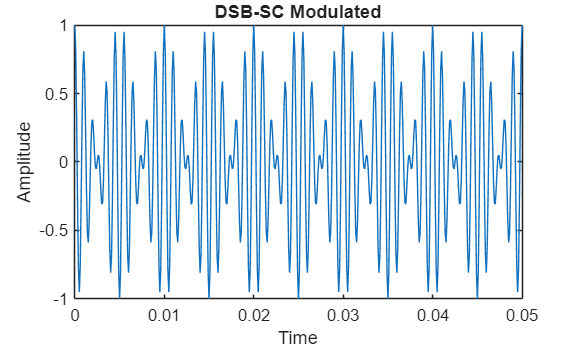


figure; plot(t, dsb_sc);
title('DSB-SC Modulated');
xlabel('Time');
ylabel('Amplitude');

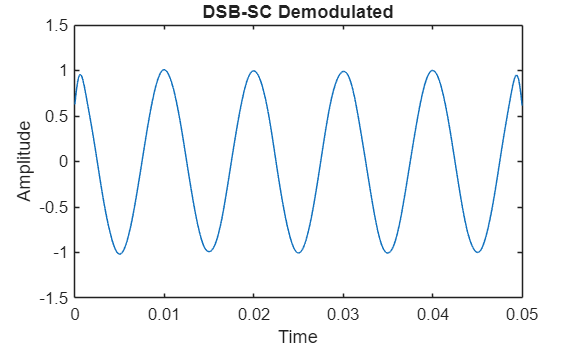


figure; plot(t, m_dsb_sc);
title('DSB-SC Demodulated');
xlabel('Time');
ylabel('Amplitude');

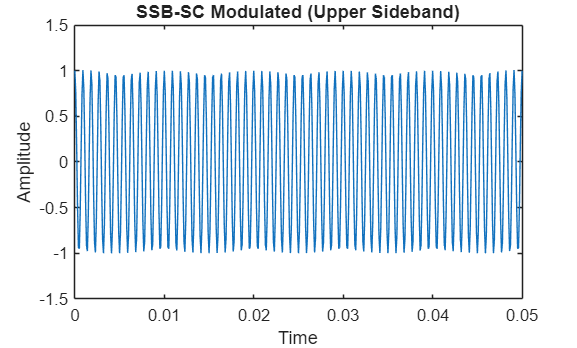


figure; plot(t, ssb_sc);
title('SSB-SC Modulated (Upper Sideband)');
xlabel('Time');
ylabel('Amplitude');

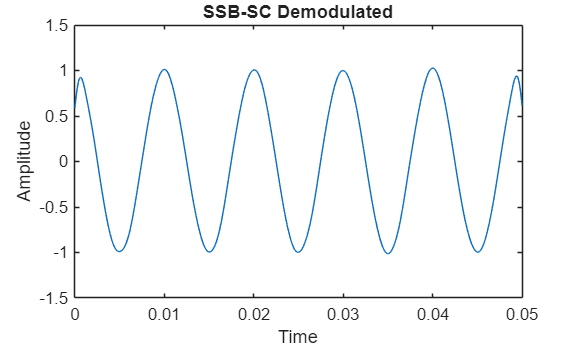


figure; plot(t, m_ssb_sc);
title('SSB-SC Demodulated');
xlabel('Time');
ylabel('Amplitude');

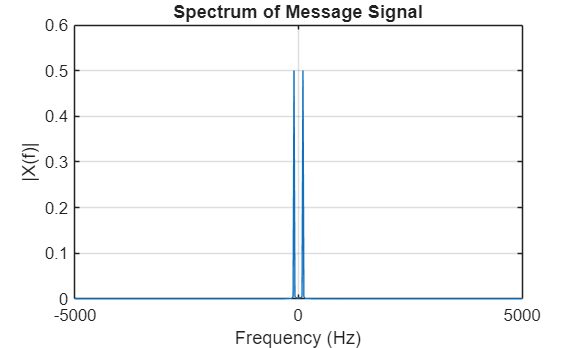



function plot_spectrum(signal, fs, title_str)
    N = length(signal);
    f = linspace(-fs/2, fs/2, N);
    X = fftshift(abs(fft(signal, N)) / N);
    figure;
    plot(f, X);
    title(title_str);
    xlabel('Frequency (Hz)');
    ylabel('|X(f)|');
    grid on;
end


plot_spectrum(m, fs, 'Spectrum of Message Signal');

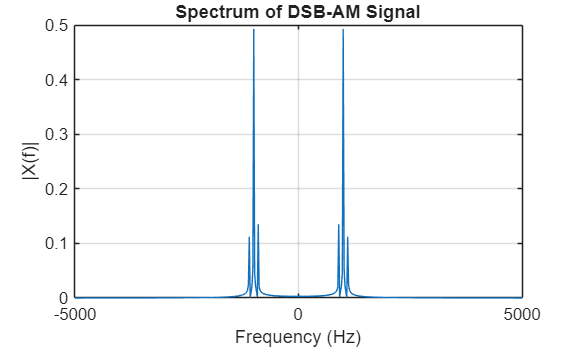

plot_spectrum(dsb_am, fs, 'Spectrum of DSB-AM Signal');

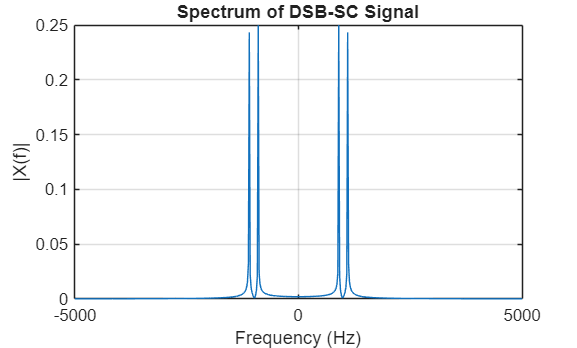

plot_spectrum(dsb_sc, fs, 'Spectrum of DSB-SC Signal');

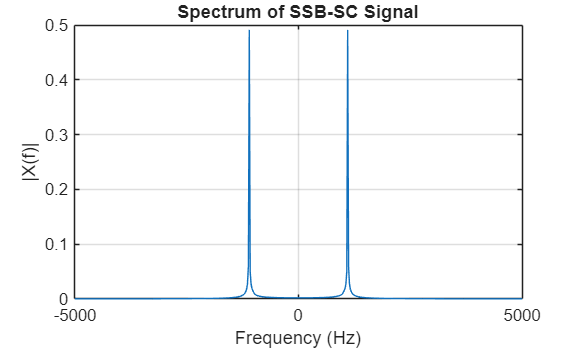

plot_spectrum(ssb_sc, fs, 'Spectrum of SSB-SC Signal');